# Simulate Physical Model

## Open Model

modelName = 'simpleHelicopter_toReduce';
open_system(modelName)

Enable or disable network trainning:

train = true;

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 300;

Create different simulation scenarios by specifying the the heat input stairs

initialScenarioVector = [[2e3:1e3:5e3] [5e3:-1e3:2.5e3]];
referenceHeatStates = {{initialScenarioVector,simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+150],simStopTime},                       
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+300],simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+450], simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+600],simStopTime}, 
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+650], simStopTime}};

Generate the simulation scenarios and save them in MAT files

for ix=1:numel(referenceHeatStates)
    generateInputs(scenarioDir, referenceHeatStates{ix}{1},...
    referenceHeatStates{ix}{2}, ix, 'heatIn')
end

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

load_system(modelName)
clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
simIn(1:numCases) = Simulink.SimulationInput(modelName);

for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    scenarioSimStopTime = aux{end};

    simIn(ix) = simIn(ix).setModelParameter('StopTime', scenarioSimStopTime);
    simIn(ix) = setVariable(simIn(ix), 'Qin', scenario{ix}.stateVecRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'Qin_time', scenario{ix}.stateVecRef{1}.Values.Time', ...
        'Workspace', modelName);
end

## Simulate

Simulate in parallel and save the results

out = parsim(simIn,'ShowSimulationManager','on');

[28-Oct-2023 22:46:08] Checking for availability of parallel pool...
[28-Oct-2023 22:46:08] Starting Simulink on parallel workers...
[28-Oct-2023 22:46:08] Loading project on parallel workers...
[28-Oct-2023 22:46:08] Configuring simulation cache folder on parallel workers...
[28-Oct-2023 22:46:08] Loading model on parallel workers...
[28-Oct-2023 22:46:19] Running simulations...
[28-Oct-2023 22:46:53] Cleaning up parallel workers...


save(fullfile(simOutDir,'simOuts'),'out') 

# Prepare Data for Training

To achieve better performance the data are resampled, normalized.

## Resample Data

Resample the data in seconds

sampleTime = 0.1; % s
timeStep = out(1).tout(2)-out(1).tout(1); % s
batchDownSample = @(x) downsample(x,sampleTime/timeStep);

for ix = 1:length(out)
    resultsTable{ix} = out(ix).logsout.extractTimetable;
end

resampledData = cellfun(batchDownSample, resultsTable,'UniformOutput', false);

commandSignals = [{'Altitude', 'Qin'}];
resampledData = cellfun(@(x) movevars(x,commandSignals{1},'Before',1), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,commandSignals{2},'Before',2), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'T3','After',8), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'P2','After',8), resampledData,'UniformOutput', false);

sigNames = resampledData{1}.Properties.VariableNames;

## Visualize Resampled data

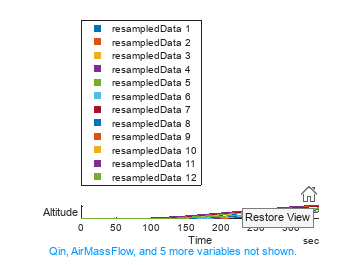

figure
stackedplot(resampledData)

## Prepare Data For Normalization

Concatenate the data using the [vertcat](https://uk.mathworks.com/help/matlab/ref/double.vertcat.html?searchHighlight=Vertcat&s_tid=doc_srchtitle) function:

concatDataTrain = [];
concatDataTrain = vertcat(resampledData{:});

calculate the mean and standard deviation of the simulation data, save the results and clear the concatenated data

meanTrain = mean(concatDataTrain);
stdTrain = std(concatDataTrain);
clear concatDataTrain
save meanTrain meanTrain
save stdTrain stdTrain

## Normalize Data

Apply gaussian normalization to the entire set of data.

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNormComp = cellfun(@(x) normalize(x, meanTrain, stdTrain), resampledData, 'UniformOutput', false);

## Prepare data for training

Define the normalized inputs and the expected responses as seen below:

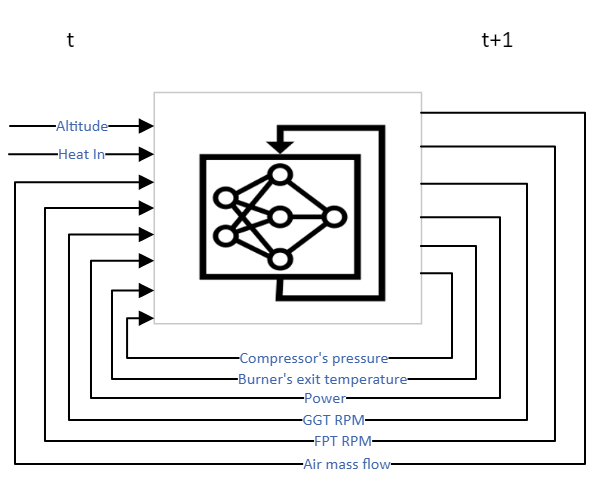

outStartIdx = length(commandSignals)+1;
inOut = @(x)[{x(1:end-1,:)} {x(2:end, outStartIdx:end)}];

aux = cellfun(inOut,dataTrainNormComp,'UniformOutput', false);

for ix=1:numel(dataTrainNormComp)
    inputTrain{ix} = table2array(aux{ix}{1});
    responseTrain{ix} = table2array(aux{ix}{2});
end
clear aux

# Train a Neural Network

## Define the Inputs/Outputs

Define the number of inputs and outputs of the neural network. Create respective datasets that correspond to the inputs and outputs of each timestep.

numFeatures = length(sigNames);
numResponses = length(sigNames)-length(commandSignals);
numHiddenUnits = 150;
dropoutProbability = 0.2;

## Define Network Architecture

Choose [lstmLayer](https://uk.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html) for timeseries prediction 

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    ];


## Define Training Options

Define solver, specify learning rate and trainnig epochs

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

## Train the Network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:02         0.01         0.95318
           50       50       00:00:46         0.01       0.0067583
          100      100       00:01:30         0.01       0.0039227
          150      150       00:02:11         0.01         0.00334
          200      200       00:02:51         0.01       0.0031083
          250      250       00:03:32        0.001       0.0030365
          300      300       00:04:17        0.001       0.0030831
          350      350       00:04:58        0.001       0.0030261
          400      400       00:05:38        0.001       0.0030354
          450      450       00:06:20       0.0001        0.003037
          500      500       00:07:01       0.0001       0.0029927
Training stopped: Max epochs completed


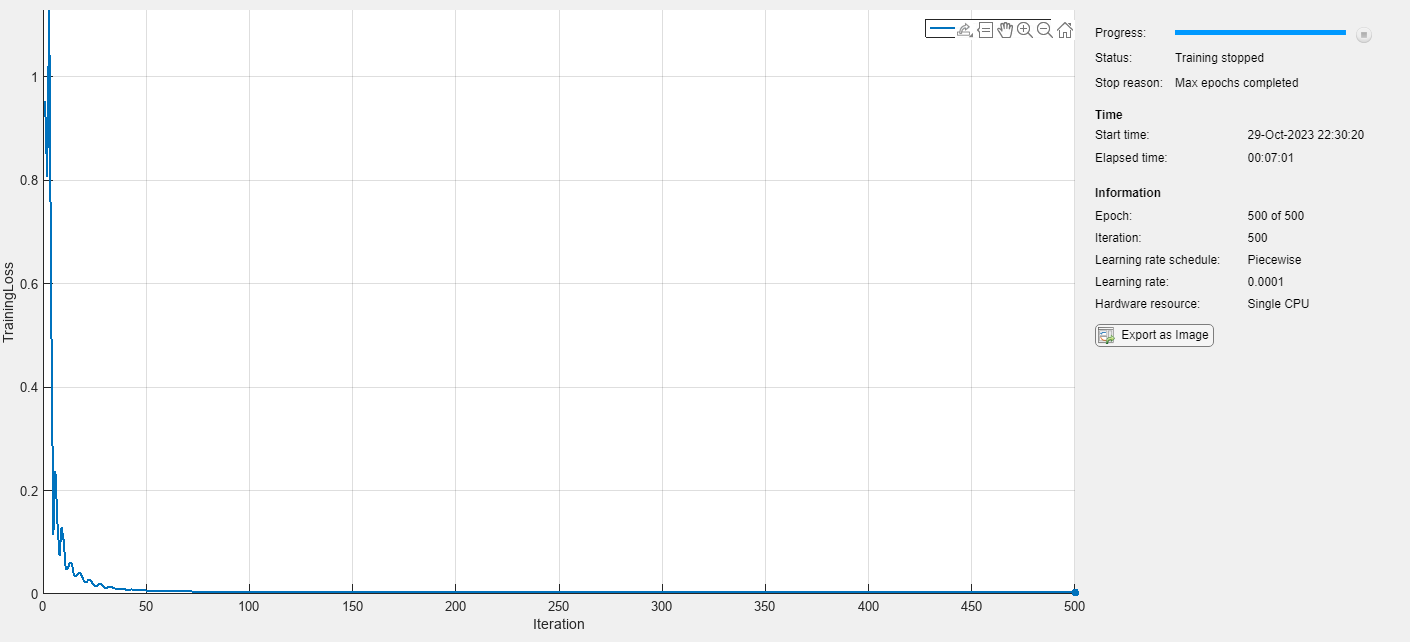

if train
    [net, traininfo] = trainnet(inputTrain,responseTrain,layers,'mean-squared-error',opts);
    net = resetState(net);
    save("turboshaftEngine\Models\Components\turboShaftEngineLSTM_ROM\turboshaft_ROM_v5.mat","net")
end

## Integrate Trained LSTM Network in Simulink

You can use recurrent neural networks in simulink by using the "Stateful Predict" block 

reducedModel = 'simpleHelicopter_ROM';
open_system(reducedModel)

# Evaluate results

Compare original and reduced model rregarding their resutls and simulation performance. This comparison is on a scenario that has not been included in the trainning.

mode = 'Custom';

## Simulate the ROM

set_param([reducedModel,'/HeatIn'],'LabelModeActivechoice', mode)
romSim = sim(reducedModel);
romRunID = Simulink.sdi.Run.getLatest;

## Simulate the Physical Model

referenceModel = 'simpleHelicopter_reference';
open_system(referenceModel)
set_param([referenceModel,'/HeatIn'],'LabelModeActivechoice', mode)
refSim = sim(referenceModel);
refRunID = Simulink.sdi.Run.getLatest;

## Test in Simulation Data Inspector

Define acceptable absolute and relative tolerance

relTol = 2e-2;
absTol = 6;

Launch comparison on the Simulation Data Inspector

Simulink.sdi.compareRuns(refRunID.id,romRunID.id,'RelTol',relTol,'AbsTol',absTol)

ans =   DiffRunResult with properties:

       MatlabVersion: '23.2.0.2365128 (R2023b)'
              RunID1: 195
              RunID2: 317
     BaselineRunName: 'Run 4: simpleHelicopter_reference'
    CompareToRunName: 'Run 6: simpleHelicopter_ROM'
               Count: 8
         DateCreated: 31-Oct-2023 14:24:54
     GlobalTolerance: [1×1 struct]
             Summary: [1×1 struct]
             Options: {'Units'  'MustMatch'}
              Status: Completed
          StopReason: []


Simulink.sdi.view

## Performance comparison

Compare the Simulation Metadata containing information regarding the initialization, execution and total time of the simulation.

The timing info for the reference simulation

refSim.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-30 14:14:47'
           WallClockTimestampStop: '2023-10-30 14:15:14'
    InitializationElapsedWallTime: 3.5377
         ExecutionElapsedWallTime: 23.4949
       TerminationElapsedWallTime: 0.0371
             TotalElapsedWallTime: 27.0697
                     ProfilerData: 'Profiler is not enabled'


The timing info for the ROM model

romSim.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-30 14:15:44'
           WallClockTimestampStop: '2023-10-30 14:16:06'
    InitializationElapsedWallTime: 1.6442
         ExecutionElapsedWallTime: 20.8833
       TerminationElapsedWallTime: 0.0449
             TotalElapsedWallTime: 22.5724
                     ProfilerData: 'Profiler is not enabled'


Compare performance:

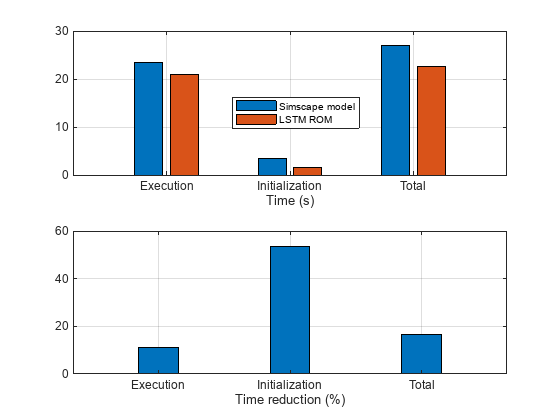

compareSimulationPerformance(refSim, romSim)

# Real-Time Simulation

Use Simulink Real-Time to simulate the model in real time:

open_system('simpleHelicopter_ROM_realTime')

 Let's take-off !

# DRAFT

## Prepare Data For Training

trainPercentage = 0.8; % the percentage of the data that they will be used for training
                       % the rest will be used for test
[dataTrain, dataTest, meanTrain, stdTrain] = prepareDataNormalization(resampledData, trainPercentage);
save meanTrain meanTrain
save stdTrain stdTrain



*PH: Envoyer des donnes*

if train
    [net, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers,opts);
    net = resetState(net);
end

## Compare with Simulink Test

import matlab.unittest.TestCase
import Simulink.sdi.constraints.MatchesSignal
import Simulink.sdi.constraints.MatchesSignalOptions

Create a test case:

testCase = TestCase.forInteractiveUse;    

Set the accepted relative and absolute tolerance:

relTol = 2e-2;
absTol = 6;

Compare different signals between ROM LSTM model and original model.

for ix=1:length(sigNames)
    basselineSig = refSim.logsout.getElement(sigNames{ix});
    romSig = romSim.logsout.getElement(sigNames{ix});
    testCase.verifyThat(romSig,MatchesSignal(basselineSig,'RelTol',relTol))
end